# Chapter 3: Curves

## Parametric Curves

We start with the helix.

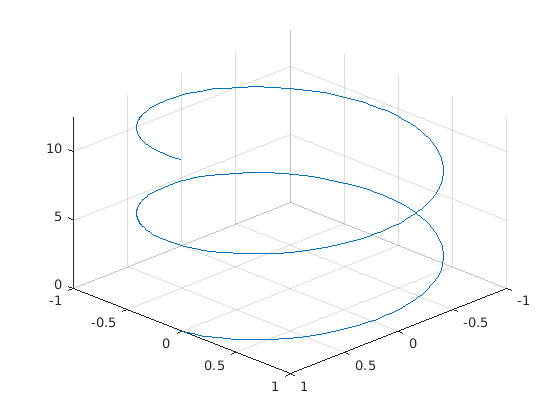

syms t s real; helix = [cos(t), sin(t), t]; 
fplot3(helix(1), helix(2), helix(3), [0, 4*pi]), view([1,1,1])

realdot = @(x,y) x*transpose(y);
vectorlength = @(x) sqrt(simplify(realdot(x,x)));
velhelix = diff(helix, t)

$$velhelix = \left(\begin{array}{ccc} -\sin\left(t\right) & \cos\left(t\right) & 1 \end{array}\right)$$

speedhelix = vectorlength(velhelix)

$$speedhelix = \sqrt{2}$$

acchelix = diff(velhelix, t)

$$acchelix = \left(\begin{array}{ccc} -\cos\left(t\right) & -\sin\left(t\right) & 0 \end{array}\right)$$

unithelix = subs(helix, t, s/sqrt(2))

$$unithelix = \left(\begin{array}{ccc} \cos\left(\frac{\sqrt{2}\,s}{2}\right) & \sin\left(\frac{\sqrt{2}\,s}{2}\right) & \frac{\sqrt{2}\,s}{2} \end{array}\right)$$

newspeed = vectorlength(diff(unithelix, s))

$$newspeed = 1$$

## The Frenet Frame

unitvector = @(x) simplify(x/vectorlength(x));
UT = diff(unithelix, s)

$$UT = \left(\begin{array}{ccc} -\frac{\sqrt{2}\,\sin\left(\frac{\sqrt{2}\,s}{2}\right)}{2} & \frac{\sqrt{2}\,\cos\left(\frac{\sqrt{2}\,s}{2}\right)}{2} & \frac{\sqrt{2}}{2} \end{array}\right)$$

UN = unitvector(diff(UT, s))

$$UN = \left(\begin{array}{ccc} -\cos\left(\frac{\sqrt{2}\,s}{2}\right) & -\sin\left(\frac{\sqrt{2}\,s}{2}\right) & 0 \end{array}\right)$$

UB = simplify(cross(UT, UN))

$$UB = \left(\begin{array}{ccc} \frac{\sqrt{2}\,\sin\left(\frac{\sqrt{2}\,s}{2}\right)}{2} & -\frac{\sqrt{2}\,\cos\left(\frac{\sqrt{2}\,s}{2}\right)}{2} & \frac{\sqrt{2}}{2} \end{array}\right)$$

curveframeplot(helix,'t',0, 4*pi,4,.6), view([2,1,2])

Unrecognized function or variable 'curveframeplot'.

xticks(''); yticks(''); zticks('');

## Curvature and Torsion

helcurv = vectorlength(diff(UT, s))
diff(UB, s)

## The Osculating Plane and Osculating Circle

First we sketch v, a, T, and N at the point (1,1) on the parabola y = x^2.

syms x real
parab = [x, x^2]; diff(parab, x)
a = diff(parab, x, 2)
T = [1,2]/norm([1,2]);
N = [-T(2), T(1)];
x = linspace(0,2);
plot(x, x.^2, 'LineWidth', 2), hold on
axis equal
quiver(1, 1, 1, 2, 'k', 'LineWidth', 1)
text(1.95, 2.85, 'v', 'FontSize', 12)
quiver(1, 1, T(1), T(2), 'k', 'LineWidth', 2)
text(1.4, 1.65, 'T', 'FontSize', 12)
quiver(1, 1, 0, 2, 'k', 'LineWidth', 1)
text(1, 3, 'a', 'FontSize', 12)
quiver(1, 1, N(1), N(2), 'k', 'LineWidth', 2)
text(0, 1.5, 'N', 'FontSize', 12)
axis off

Now we want to draw an osculating circle for the helix. Let's pick the point t=2pi as the point of tangency, which corresponds to [1, 0, 2*pi] in rectangular coordinates. Next to this, we draw a plot of the evolute of the helix, which is another helix.

N = [-1, 0, 0];
T = sym([0, 1/sqrt(2), 1/sqrt(2)])
radiuscurv = 1/helcurv;
centercurv = [1, 0, 2*sym('pi')] + radiuscurv*N
osccirc = centercurv + radiuscurv*(cos(t)*T + sin(t)*N)
subplot(1,2,1)
fplot3(helix(1), helix(2), helix(3), [0, 4*pi]), hold on
fplot3(osccirc(1), osccirc(2), osccirc(3), [0, 2*pi], 'm'), axis equal, hold off
title ''
evolute = unithelix + radiuscurv*UN;
subplot(1,2,2)
fplot3(evolute(1), evolute(2), evolute(3), [0, 4*pi*sqrt(2)]), axis equal

## Two More Examples

velocity = @(r, t) diff(r, t);
acceleration = @(r, t) simplify(diff(r, t, 2));
thirdder = @(r, t) simplify(diff(acceleration(r,t),t));
speed = @(r, t) vectorlength(velocity(r, t));
vta = @(r, t) simplify(cross(velocity(r, t), ...
acceleration(r, t)));
UT = @(r, t) unitvector(velocity(r, t));
UN = @(r, t) unitvector(diff(UT(r, t), t));
UB = @(r, t) simplify(cross(UT(r, t), UN(r, t)));
curvature = @(r, t) simplify(vectorlength(vta(r, t))/speed(r, t)^3);
torsion = @(r, t) simplify ...
    (realdot(vta(r, t), thirdder(r, t))/realdot(vta(r, t), vta(r, t)));

## The Astroid

astroid = [cos(t)^3, sin(t)^3, cos(2*t)];
fplot3(astroid(1), astroid(2), astroid(3), [0, 2*pi])

velocity(astroid, t)
speed(astroid, t)
acceleration(astroid, t)
UT(astroid, t)
UN(astroid, t)
UB(astroid, t)
curvature(astroid, t)
torsion(astroid, t)
simplify(subs(ans, cos(t) - cos(t)^3, cos(t)*sin(t)^2))

## The Cycloid

cyc = [t - sin(t), 1 - cos(t)];
fplot(cyc(1), cyc(2), [0, 4*pi]), axis equal tight

cycloid = [cyc, 0];
velocity(cycloid, t)
acceleration(cycloid, t)
speed(cycloid, t)